folder = "C:\Users\Nickolay\Desktop\ITMO-courses\7_term\Discrete_control_systems\lab3\tex\images\";

simtime = 7;
out = sim("lab3_deadbeat.slx", simtime);

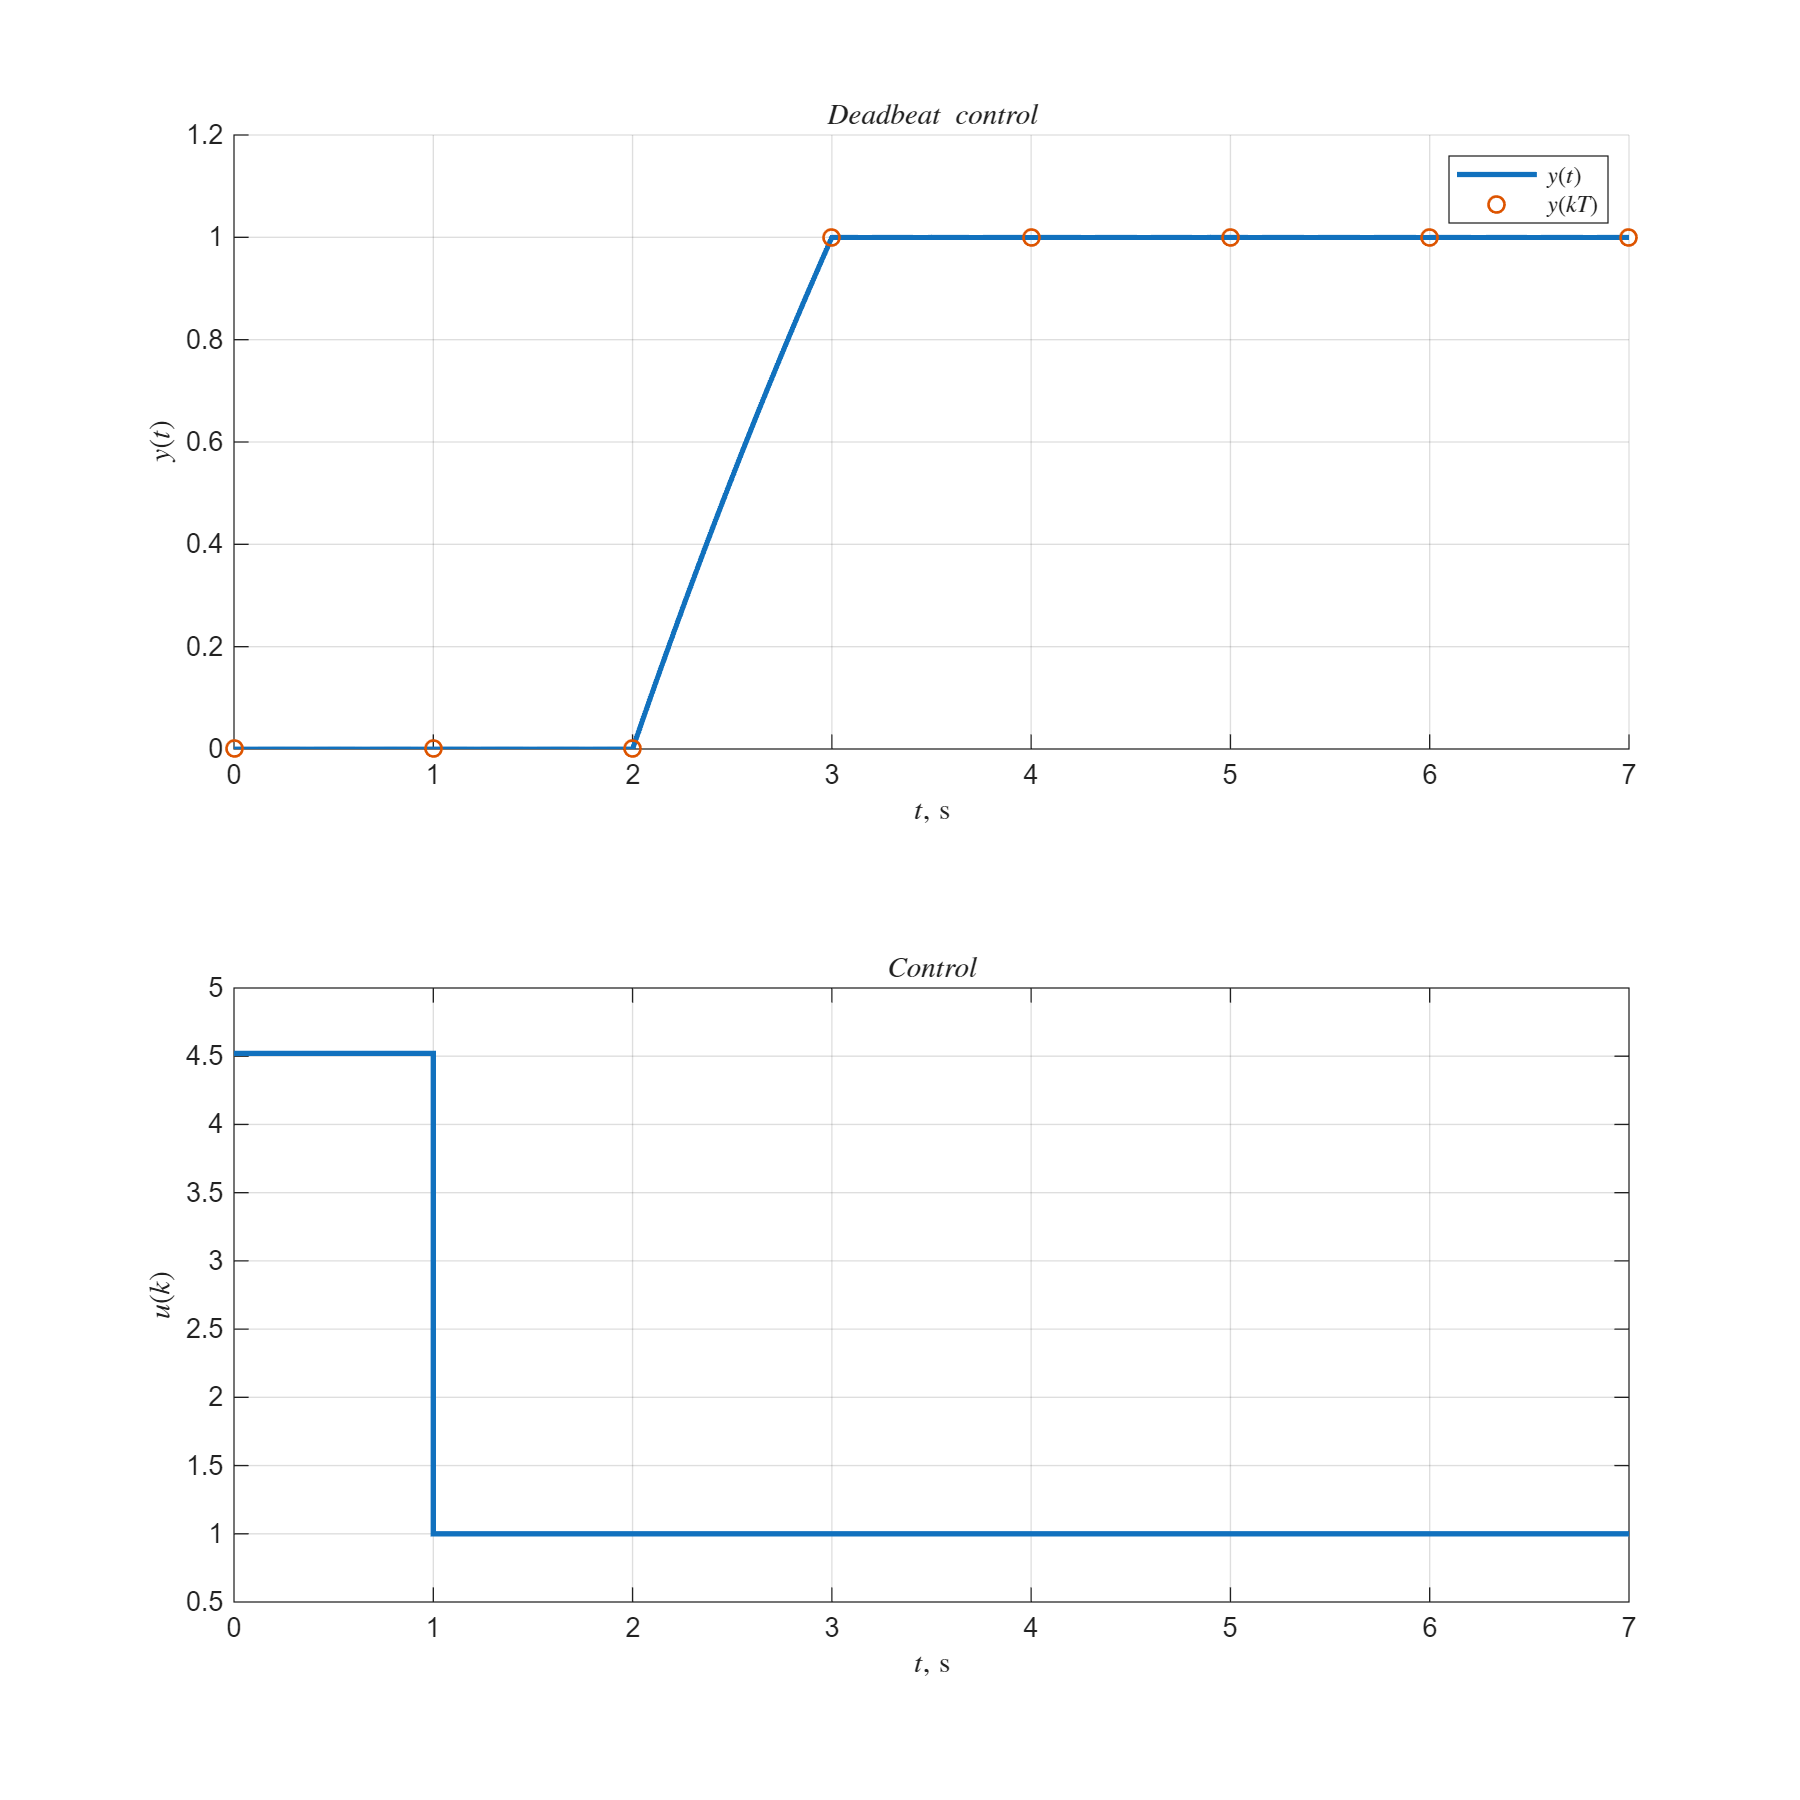


y = out.y.Data;
t = out.y.Time;
ys = out.ys.Data;
ts = out.ys.Time;
u = out.u.Data;
tu = out.u.Time;

f = figure;
f.Position = [100 100 900 900];

subplot(2,1,1);
hold on;
plot(t, y, LineWidth=2);
plot(ts, ys, "o", LineWidth=1);
hold off;

legend({"$y(t)$", "$y(kT)$"}, Interpreter="latex");
grid on;
title("$Deadbeat\ control$", Interpreter="latex");
xlabel("$t,\;\mathrm{s}$", Interpreter="latex");
ylabel("$y(t)$", Interpreter="latex");

subplot(2,1,2);
stairs(tu, u, LineWidth=2);
grid on;
title("$Control$", Interpreter="latex");
xlabel("$t,\;\mathrm{s}$", Interpreter="latex");
ylabel("$u(k)$", Interpreter="latex");

exportgraphics(f, fullfile(folder, "task1_deadbeat.png"), Resolution=600);

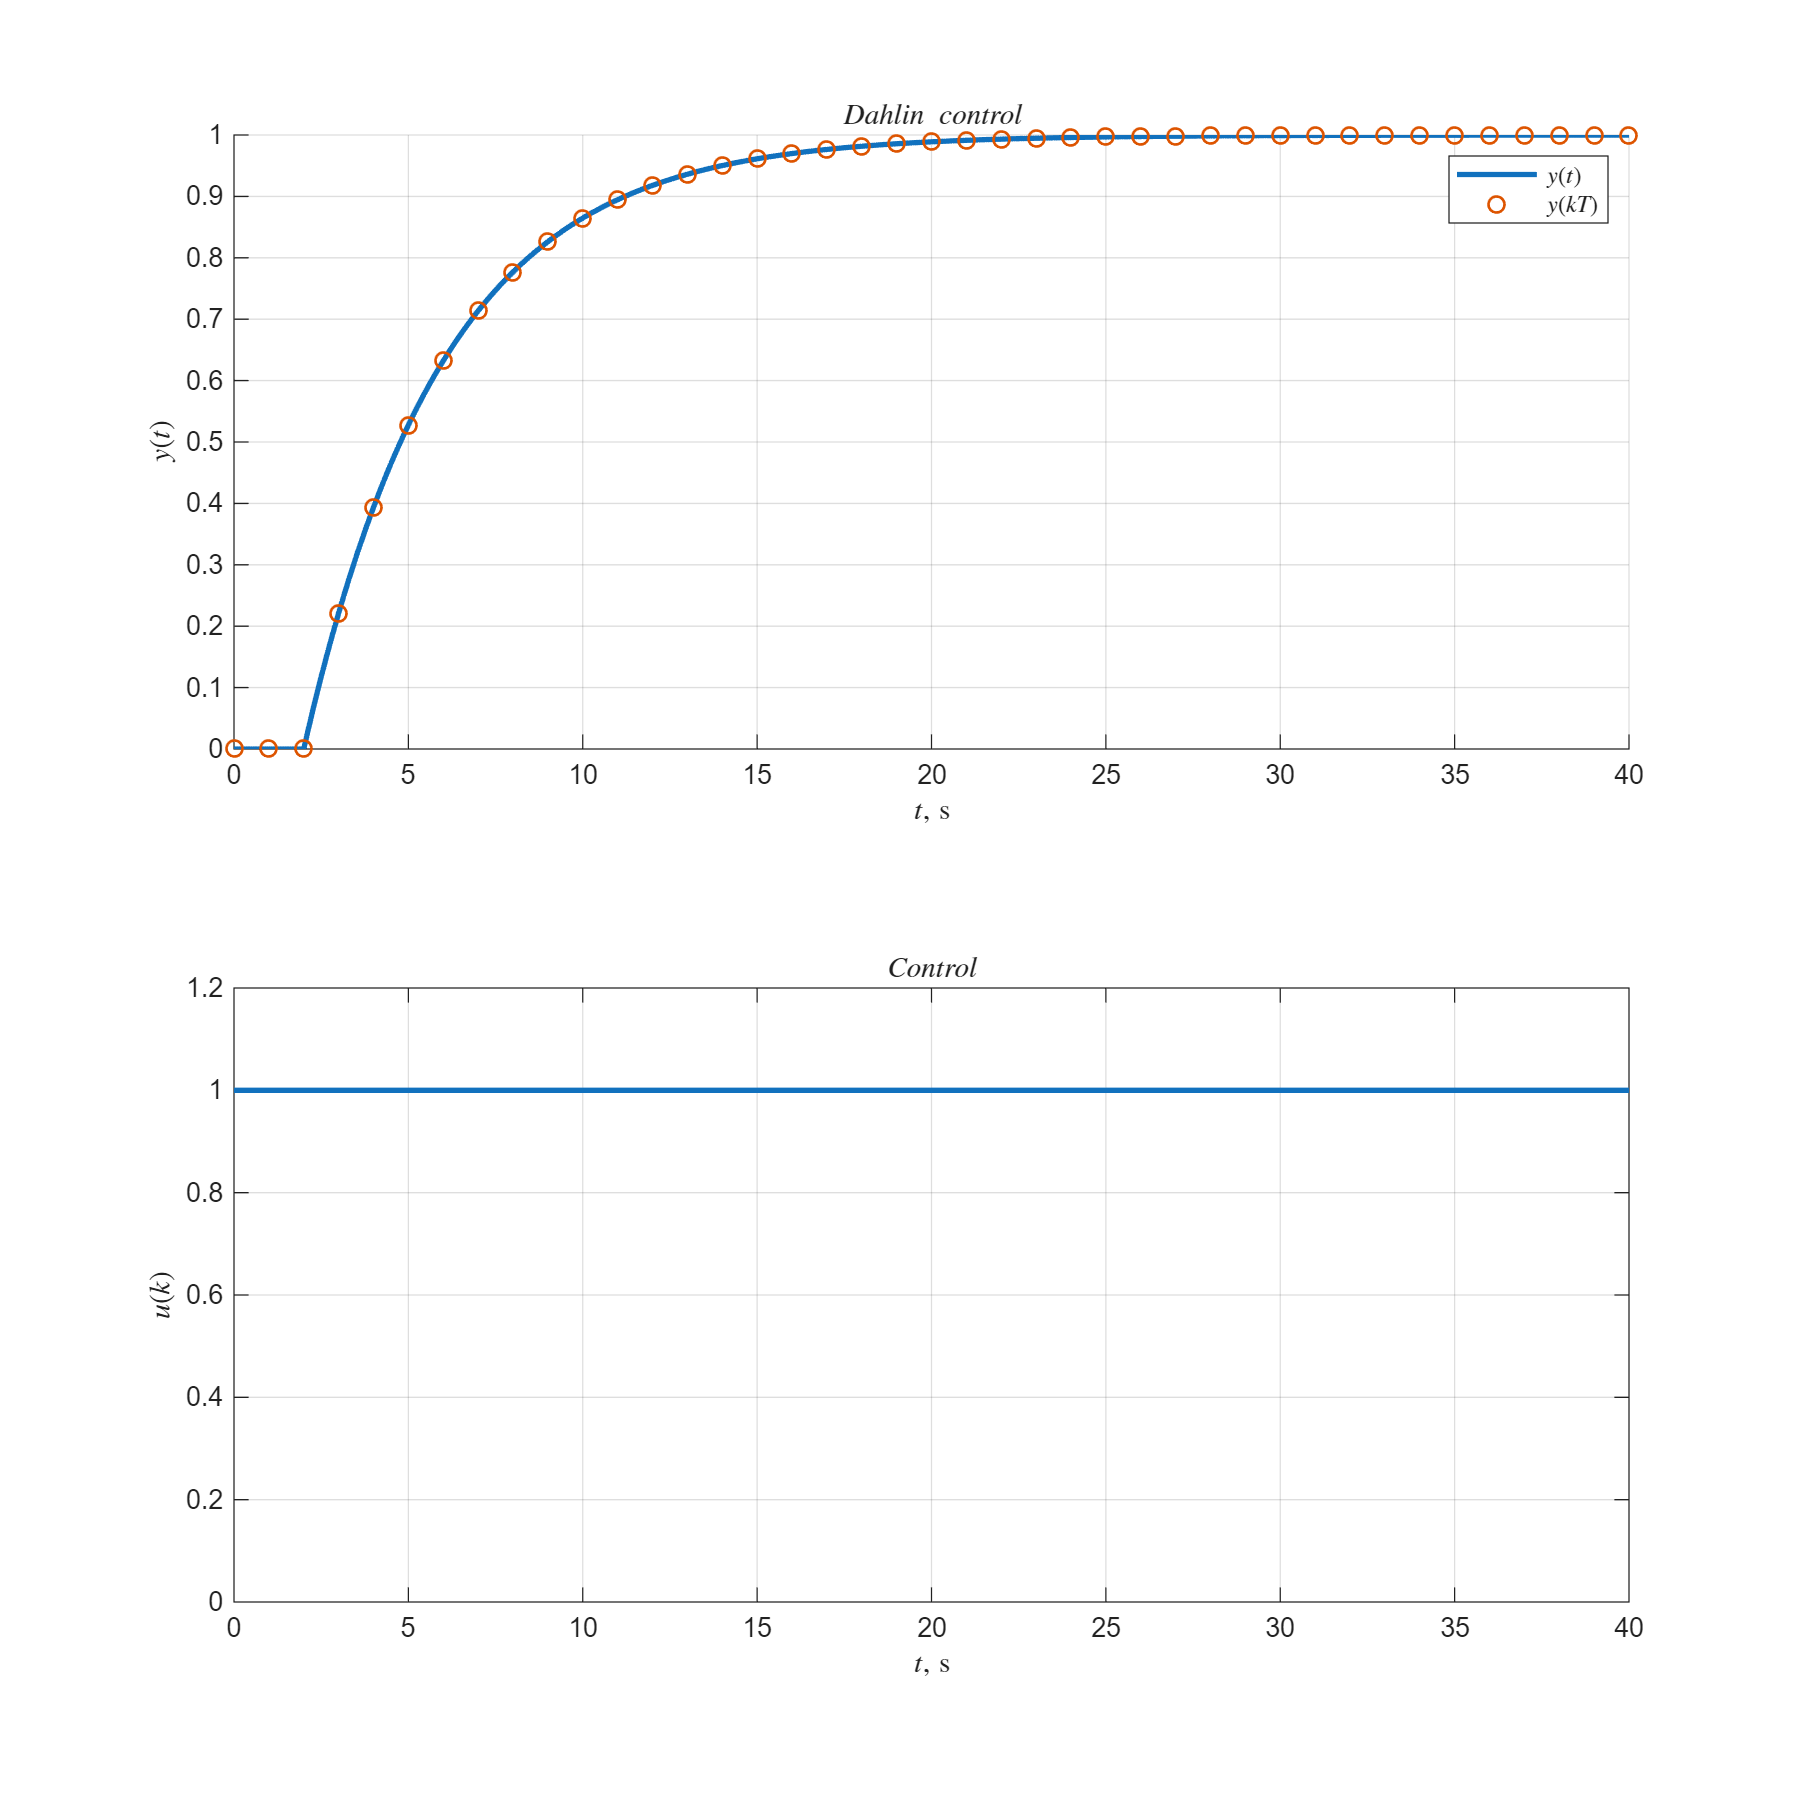



simtime = 40;
out = sim("lab3_dahlin.slx", simtime);

y = out.y.Data;
t = out.y.Time;
ys = out.ys.Data;
ts = out.ys.Time;
u = out.u.Data;
tu = out.u.Time;

f = figure;
f.Position = [100 100 900 900];

subplot(2,1,1);
hold on;
plot(t, y, LineWidth=2);
plot(ts, ys, "o", LineWidth=1);
hold off;

legend({"$y(t)$", "$y(kT)$"}, Interpreter="latex");
grid on;
xlim([0 40]);
title("$Dahlin\ control$", Interpreter="latex");
xlabel("$t,\;\mathrm{s}$", Interpreter="latex");
ylabel("$y(t)$", Interpreter="latex");

subplot(2,1,2);
stairs(tu, u, LineWidth=2);
grid on;
ylim([0 1.2]);
xlim([0 40]);
title("$Control$", Interpreter="latex");
xlabel("$t,\;\mathrm{s}$", Interpreter="latex");
ylabel("$u(k)$", Interpreter="latex");

exportgraphics(f, fullfile(folder, "task2_dahlin.png"), Resolution=600);

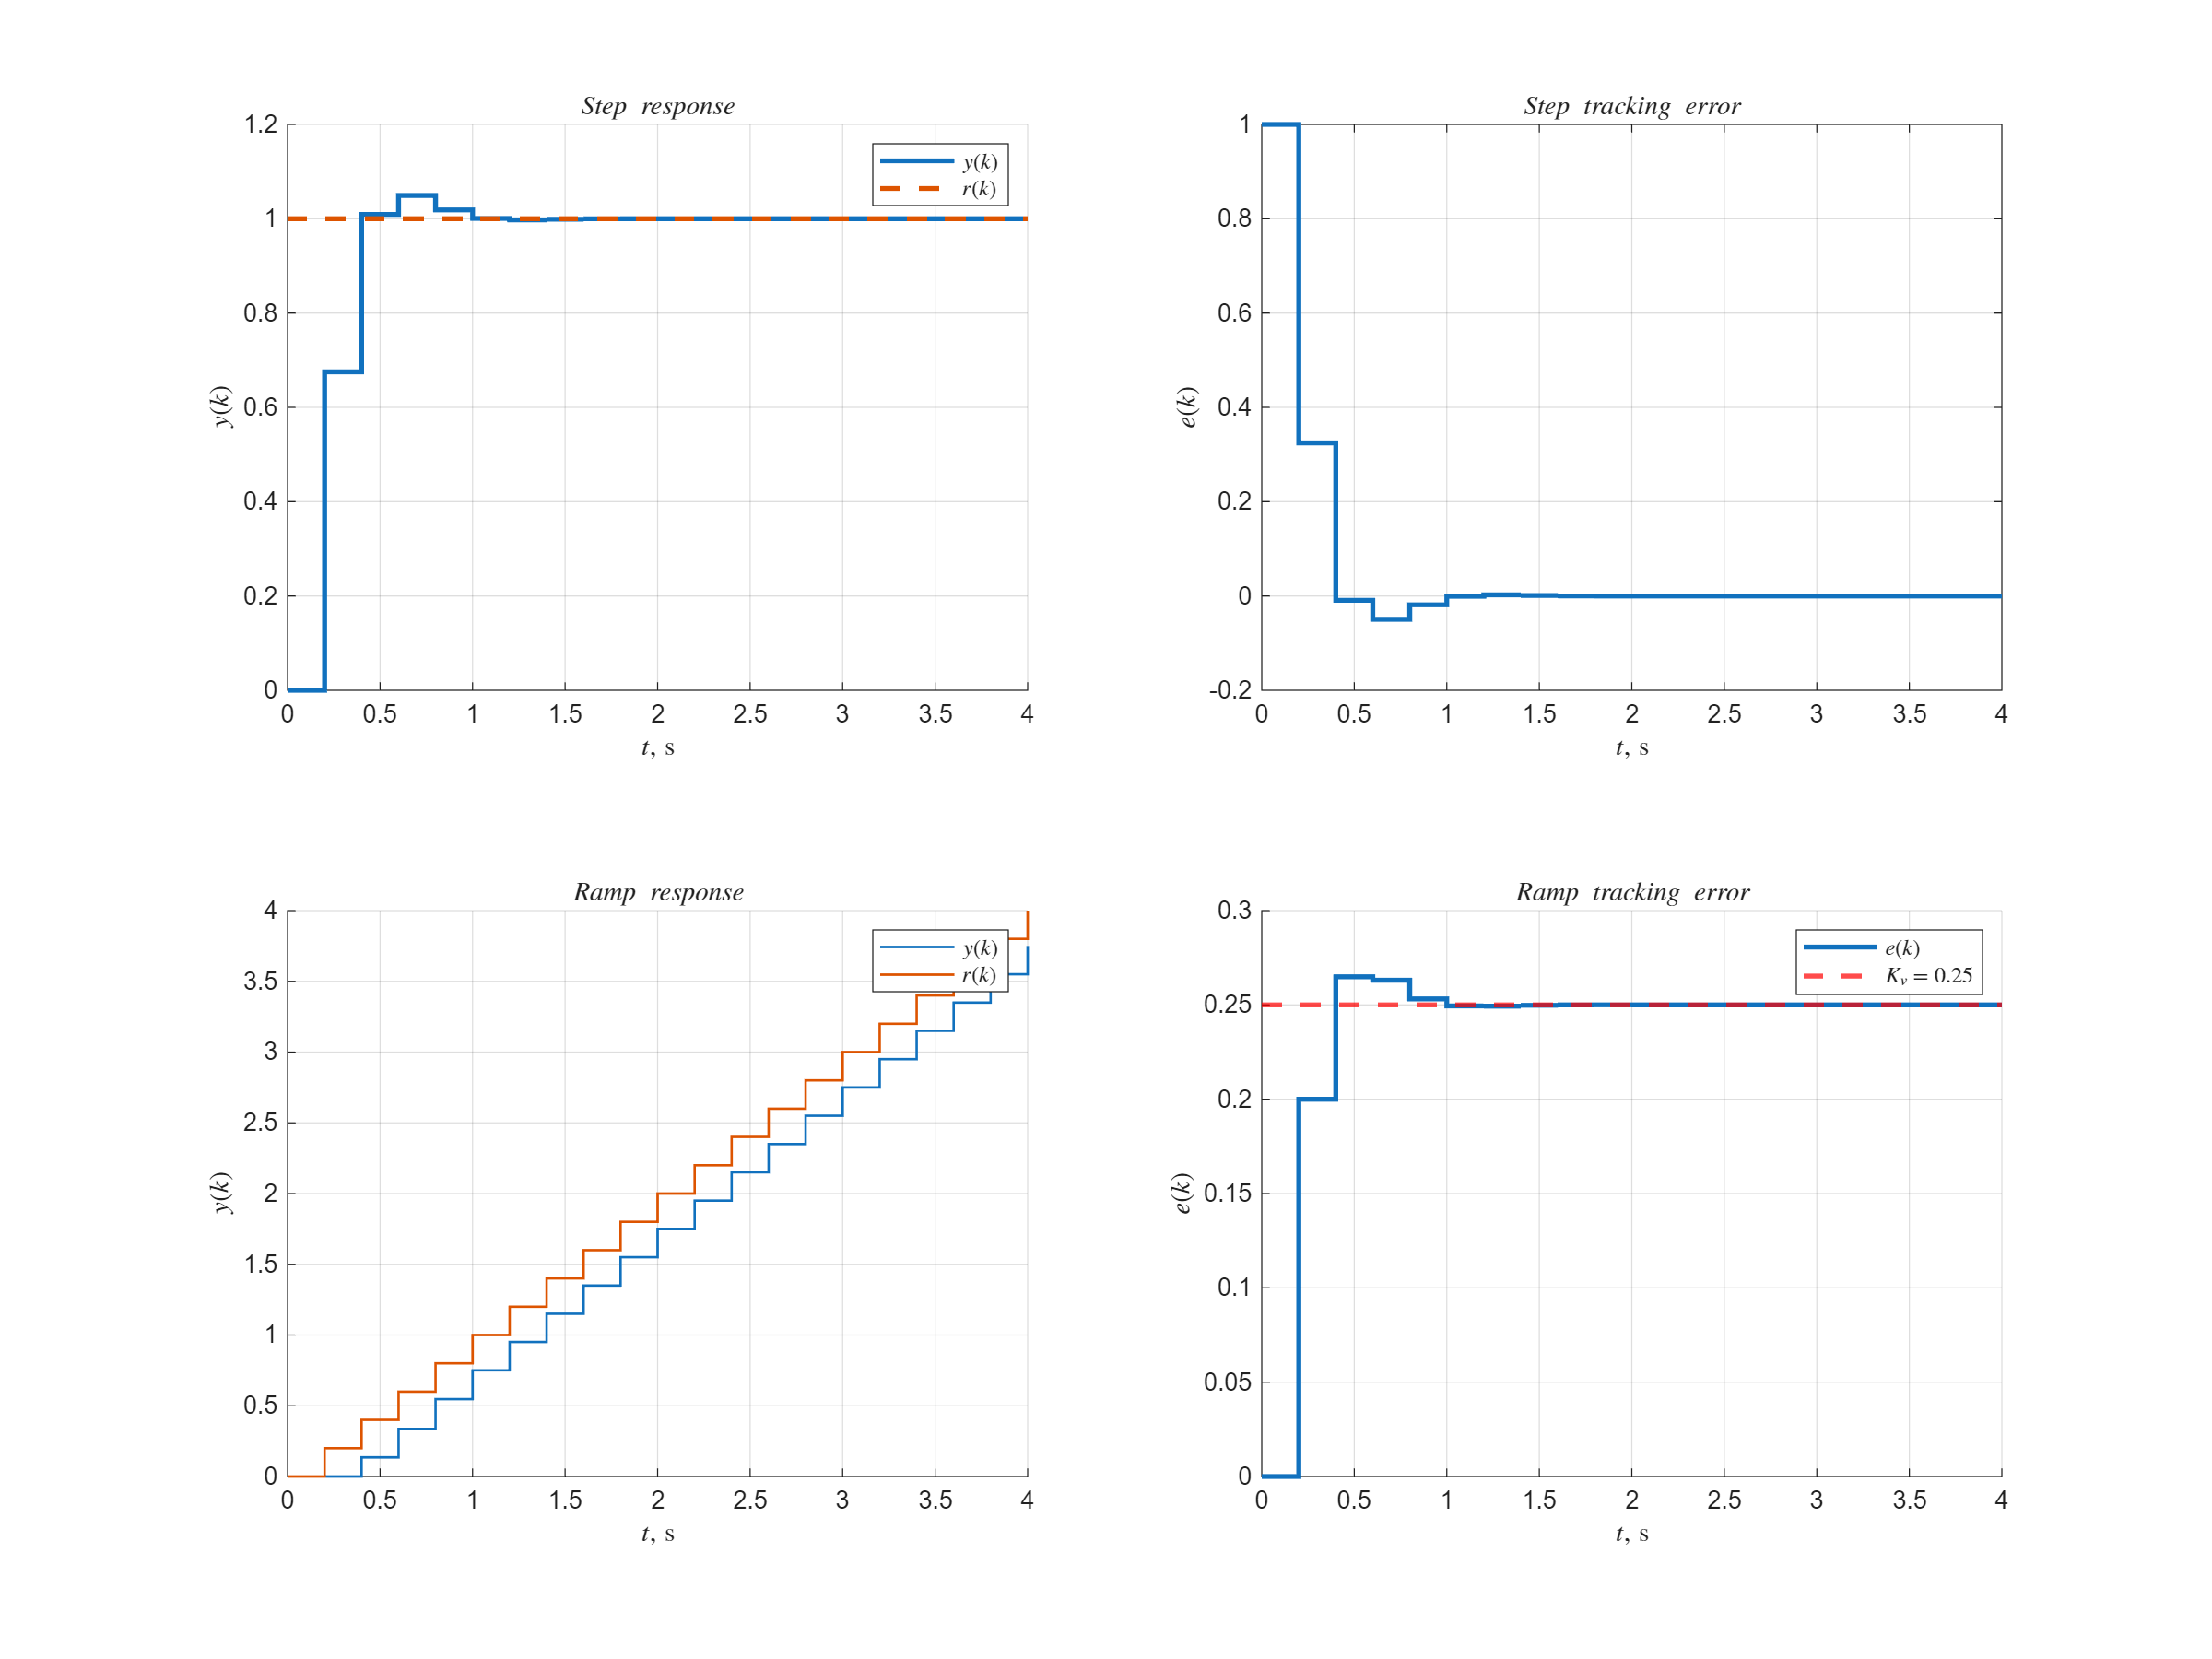



Kv = 0.25;
simtime = 4;
out = sim("lab3_poles.slx", simtime);

r1 = out.r_step.Data;
tr1 = out.r_step.Time;
y1 = out.y_step.Data;
t1 = out.y_step.Time;
e1 = out.e_step.Data;
te1 = out.e_step.Time;

r2 = out.r_ramp.Data;
tr2 = out.r_ramp.Time;
y2 = out.y_ramp.Data;
t2 = out.y_ramp.Time;
e2 = out.e_ramp.Data;
te2 = out.e_ramp.Time;

f = figure;
f.Position = [100 100 1200 900];

subplot(2,2,1);
hold on;
stairs(t1, y1, LineWidth=2);
stairs(tr1, r1, LineStyle="--", LineWidth=2);
hold off;

legend({"$y(k)$", "$r(k)$"}, Interpreter="latex");
grid on;
title("$Step\ response$", Interpreter="latex");
xlabel("$t,\;\mathrm{s}$", Interpreter="latex");
ylabel("$y(k)$", Interpreter="latex");

subplot(2,2,2);
stairs(te1, e1, LineWidth=2);
grid on;
title("$Step\ tracking\ error$", Interpreter="latex");
xlabel("$t,\;\mathrm{s}$", Interpreter="latex");
ylabel("$e(k)$", Interpreter="latex");

subplot(2,2,3);
hold on;
stairs(t2, y2, LineWidth=1);
stairs(tr2, r2, LineWidth=1);
hold off;

legend({"$y(k)$", "$r(k)$"}, Interpreter="latex");
grid on;
title("$Ramp\ response$", Interpreter="latex");
xlabel("$t,\;\mathrm{s}$", Interpreter="latex");
ylabel("$y(k)$", Interpreter="latex");

subplot(2,2,4);
hold on;
stairs(te2, e2, LineWidth=2);
yline(Kv, color="r", LineStyle="--", LineWidth=2);
hold off;

legend({"$e(k)$", "$K_v=0.25$"}, Interpreter="latex");
grid on;
title("$Ramp\ tracking\ error$", Interpreter="latex");
xlabel("$t,\;\mathrm{s}$", Interpreter="latex");
ylabel("$e(k)$", Interpreter="latex");

exportgraphics(f, fullfile(folder, "task3_poles.png"), Resolution=600);